# Well-Posed vs Ill-Posed Problems

A problem Ax = b is WELL POSED if:

1) Solution exists

2) Solution is unique

3) Solution depends continuously on data

We study conditioning using singular values and condition number.

clc; clear; close all;

## Example of Well Posed Matrix (Random Matrix)

n = 100;
A1 = randn(n);              % Random Full rank matrix

[U1, S1, V1] = svd(A1);
singular_vals_A1 = diag(S1);

% Condition number
cond_A1 = cond(A1);
disp('Condtion number of Well Posed Matrix')

Condtion number of Well Posed Matrix


disp(cond_A1)

   2.6688e+02



## Singular Value Spectrum (Well Posed)

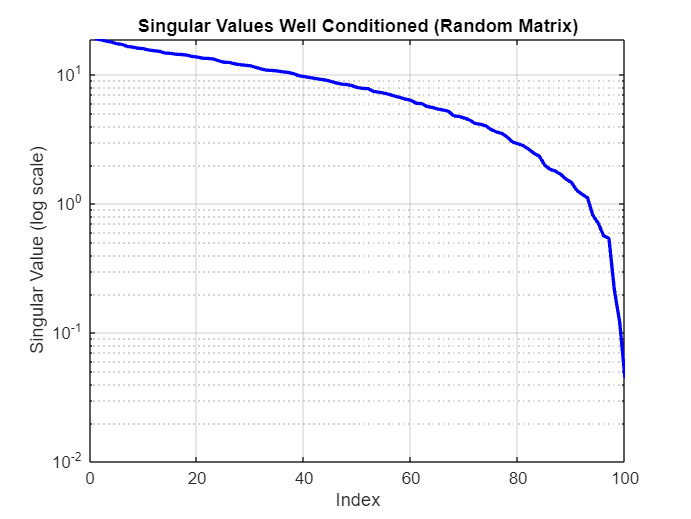

figure;
semilogy(singular_vals_A1, 'b', 'LineWidth', 2);
grid on;
title('Singular Values Well Conditioned (Random Matrix)');
xlabel('Index');
ylabel('Singular Value (log scale)');

## Example of Ill Posed Matrix 

function A = rank_deficient_operator(n, r)  %  change the rank deficient operator. 
    [U, ~, V] = svd(randn(n, n), 'econ');

    s = linspace(1.0, 0.1, n);
    s(r+1:end) = 0.0

    A = U * diag(s) * V';
end
A2 = rank_deficient_operator(n, 12)

s =    1.0000e+00   9.8163e-01   9.6327e-01   9.4490e-01   9.2653e-01   9.0816e-01   8.8980e-01   8.7143e-01   8.5306e-01   8.3469e-01   8.1633e-01   7.9796e-01            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0


A2 =    1.3158e-01  -2.0571e-02  -6.0731e-02   4.4825e-02  -4.3563e-02  -6.9044e-03  -6.8540e-02  -1.2375e-02  -3.2415e-02  -4.7513e-02  -5.8947e-03   6.7190e-02   1.4285e-01   1.9482e-04   3.9231e-02  -5.2727e-03   4.5382e-02   6.9503e-02   1.6637e-01   6.6272e-02   6.4290e-02   4.1714e-02  -1.8283e-02  -3.6733e-02   9.0661e-02  -1.9973e-02   1.0457e-01   3.2230e-02  -1.3622e-02   4.2581e-02   5.2019e-02   4.7994e-02  -1.0235e-01   5.2398e-02   5.5548e-02   5.8256e-02  -1.9423e-02  -5.1780e-03  -2.1985e-02  -6.1525e-02  -1.8504e-02  -8.8446e-02  -3.3775e-02   1.0171e-02   9.6270e-02   9.3053e-02  -3.2422e-02  -3.8313e-02  -1.2408e-03  -6.6896e-03
   8.0764e-02  -2.0884e-01  -5.5866e-02   1.0116e-02  -2.3247e-02   8.3232e-03   2.5376e-02  -4.8890e-02  -2.2191e-02   7.6967e-02   5.4850e-02  -6.6288e-02   2.3799e-02  -1.0001e-01  -8.5192e-02  -1.1592e-01  -6.2558e-04  -5.3127e-02   2.1891e-02  -5.4713e-02  -1.5033e-01   9.4008e-02   5.6680e-02   9.7693e-02   9.6917e-02   1.4672e-02  -4.6

[U2, S2, V2] = svd(A2);
singular_vals_A2 = diag(S2);

% Condition number
cond_A2 = cond(A2);

disp('Condition number of Ill posed Matrix:')

Condition number of Ill posed Matrix:


disp(cond_A2)

   2.9813e+17



## Singular Value Spectrum (Ill Posed)

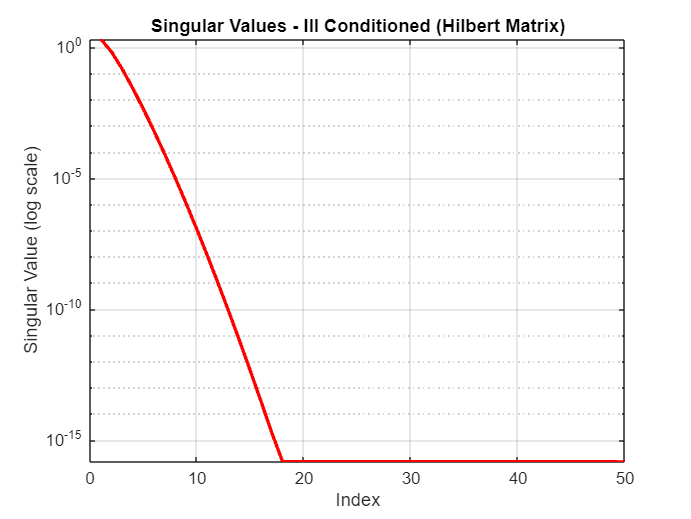

figure;
semilogy(singular_vals_A2, 'r', 'LineWidth', 2); vv
grid on;
title('Singular Values - Ill Conditioned Rank Deficient Matrix');
xlabel('Index');
ylabel('Singular Value (log scale)');

## Comparison of Spectra

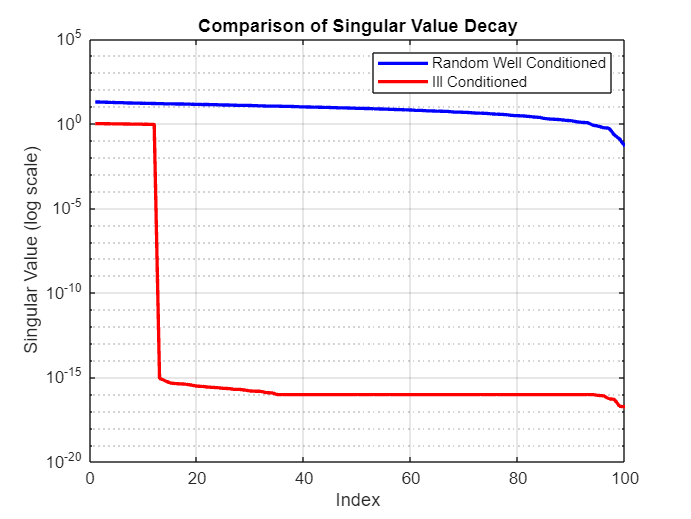

figure;
semilogy(singular_vals_A1, 'b', 'LineWidth', 2); hold on;
semilogy(singular_vals_A2, 'r', 'LineWidth', 2);
grid on;

legend('Random Well Conditioned',  'Ill Conditioned');
title('Comparison of Singular Value Decay');
xlabel('Index');
ylabel('Singular Value (log scale)');

## Sensitivity to Noise (Instability Demonstration)

b = randn(m,1);

% Solve Ax = b
x_original = A2 \ b;


% Add tiny noise
b_noisy = b + 1e-6*randn(m,1);

x_noisy = A2 \ b_noisy;


% Measure difference
difference = norm(x_original - x_noisy);

disp('Difference between solutions due to tiny noise:')

Difference between solutions due to tiny noise:


disp(difference)

   1.6470e+13



## Stability Check for Well Posed Matrix

b1 = randn(n,1);

x1_original = A1 \ b1;
x1_noisy    = A1 \ b1_noisy;
difference_well = norm(x1_original - x1_noisy);

x2_original = A2 \ b1;

x2_noisy    = A2 \ b1_noisy;

difference_ill = norm(x2_original - x2_noisy);

disp('Difference for Well-Conditioned Matrix:')

Difference for Well-Conditioned Matrix:


disp(difference_well)

   7.4259e+00




disp('Difference for Ill-Conditioned Matrix:')

Difference for Ill-Conditioned Matrix:


disp(difference_ill)

   1.2075e+18



## Condition Number via Singular Values

cond_manual_A1 = max(singular_vals_A1) / min(singular_vals_A1);
cond_manual_A2 = max(singular_vals_A2) / min(singular_vals_A2);

disp('Manual Condition Number (Random):')

Manual Condition Number (Random):


disp(cond_manual_A1)

   2.1604e+02





disp('Manual Condition Number (Hilbert):')

Manual Condition Number (Hilbert):


disp(cond_manual_A2)

   5.1102e+16



Condition Number of Original Matrix:


   1.7176e+19



Condition Number After Jacobi Preconditioning:


   1.5312e+19

